# Trial 1: Asymptotic Efficiency under Repeated Measurement 

clear;
close all;
clc;

## 1. Settings

### 1.1 enviroment settings

%set room size, robot size, and the true pose
Room_Length=50; Room_Width=50;
Robot_Size=3;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t=[0;25];

### 1.2 simulation settings

T=[1,10,100,1000,10000,100000,1000000,10000000]; %number T of repeated ranging
sigma=0.05*[1,2,3,4,5,6];%Standard Deviations
L=10;                   %Monte-Carlo rounds
%matrix to store simulation results
%GN-SDP
Y1_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
time_1=zeros(length(T),1);


## 2. For different number T of repeated ranging

for o=1:length(T)
    M=3; % M*T(o) anchors
    N=2; % N tags
    [A,S,Mt]=setting(T(o),Room_Length,Room_Width,Robot_Size,M,N);

    %mse
    mse_R1_c=0; mse_R1_a=0; mse_t1=0;

    %true distance
    Sa=R*S+t; %tags' coordinate in global frame
    relative_position=zeros(2,Mt*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*Mt+1:i*Mt)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)'; %(Mt*N,1)
    Sigma=zeros(1,Mt*N); %standard deviations
    for i=1:N
        Sigma((i-1)*Mt+1:i*Mt)=repmat(sigma((i-1)*M+1:i*M),1,T(o));
    end

#### SDP- precalculation    

    tic
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    c_norm = repmat((vecnorm(S))',Mt,1); %(Mt*N,1),||c||
    C=zeros(Mt*N,1);
    for i=1:N
        C((i-1)*Mt+1:i*Mt,:)=c_norm(i).^2;
    end
    time_1(o)=time_1(o)+toc;

### 2.1 Monte-Carlo Runs 

    for l=1:L
        d=relative_distance+Sigma'.*randn(Mt*N,1); %(Mt*N,1) distance measurements corrupted by Gaussian noises
        d_square=d.^2;
        %GN-SDP
        tic;
        d1=d_square-(vecnorm(repmat(A,1,N))').^2-C;%(Mt*N,1)
        %       Rn=4*(d.*Sigma').^2+2*(Sigma').^4;
        Rn=4*(d.*Sigma').^2;  %ignore chi-squared random variable
        [R1,t1]= SDP(A,S,d1,Rn);
        [R1,t1]=Gauss_Newton(R1,t1,A,S,d,Sigma);
        time_1(o)=time_1(o)+toc/L;

        %MSE    
        %GN-SDP
        mse_R1_c=mse_R1_c+norm(R1-R,'fro')^2;
        mse_R1_a=mse_R1_a+angular_distance(R1,R)^2;
        mse_t1=mse_t1+norm(t1-t)^2;     
        if mode(l,10)==0 %iteration tracking
            l
        end
    end

### 2.2 RMSE

    %GN-SDP
    Y1_r(o,1)=sqrt(mse_R1_c/L);
    Y1_r(o,2)=sqrt(mse_R1_a/L);
    Y1_r(o,3)=sqrt(mse_t1/L);

### 2.3 Constrained Cramer Rao Lower Bound

    o
end

o = 1

o = 2

o = 3

o = 4

o = 5

o = 6

o = 7

o = 8

% save('Trial1_plot.mat','T','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')

## 3. Plot

### 3.1 RMSE and number T of repeated ranging

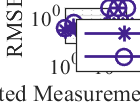

figure(1)
%GN-SDP
loglog(T,Y1_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
loglog(T,Y1_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold off

set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('RMSE')
legend({'GN-SDP(R)','GN-SDP(t)'},'Location','southwest')
grid on

### 3.2 computation time for different methods

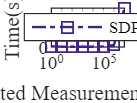

figure(2)
%GN-SDP
semilogx(T,time_1,'-.s','LineWidth',1,'MarkerSize',6,'Color','#42218E');
set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('Time(s)')
legend( 'SDP','Location','Best')
grid on

save('time_GNSDP.mat','time_1')